%%%%%%%%%%%%%%%%

graphSet;

repertoire = './'; % Chemin d'acces au code compile (NB: enlever le ./ sous Windows)
executable = 'Exercice6'; % Nom de l'executable (NB: ajouter .exe sous Windows)
input = 'cConfig.in'; % Nom du fichier d'entree de base

nsimul = 5; % Nombre de simulations a faire

N = logspace(2,4, nsimul);

paramstr = 'N'; % Nom du parametre a scanner
param = floor(N); % Valeurs du parametre a scanner

## Simulations %%

%%%%%%%%%%%%%%%%%

output = cell(1, nsimul); % Tableau de cellules contenant le nom des fichiers de sortie
for i = 1:nsimul
    output{i} = [paramstr, '=', num2str(param(i))];
    % Execution du programme en lui envoyant la valeur a scanner en argument
    cmd = sprintf('wsl %s%s %s N1=%.15g N2=%.15g  output=%s', repertoire, executable, input, param(i) , param(i),output{i});
    disp(cmd)
    system(cmd);
end

wsl ./Exercice6 cConfig.in N1=100 N2=100  output=N=100


	output=N=100
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=100
	N2=100


wsl ./Exercice6 cConfig.in N1=316 N2=316  output=N=316


	output=N=316
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=316
	N2=316


wsl ./Exercice6 cConfig.in N1=1000 N2=1000  output=N=1000


	output=N=1000
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=1000
	N2=1000


wsl ./Exercice6 cConfig.in N1=3162 N2=3162  output=N=3162


	output=N=3162
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=3162
	N2=3162


wsl ./Exercice6 cConfig.in N1=10000 N2=10000  output=N=10000


	output=N=10000
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=10000
	N2=10000


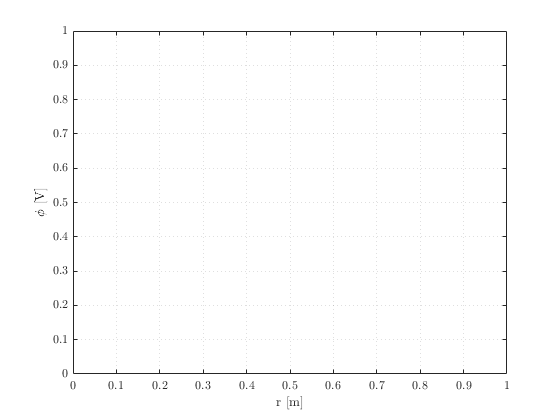


fPhi = figure;
H = 5;
W = 8;
fPhi.PaperUnits='centimeters';
fPhi.InvertHardcopy='on';
fPhi.PaperSize=[W H];
fPhi.PaperPosition=[0 0 W H];


axPhi = axes(fPhi);
hold on
xlabel('r [m]')
ylabel('$\phi$ [V]')
grid on, box on

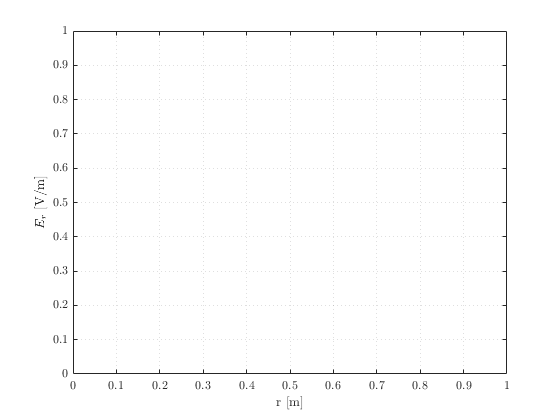



fEr = figure;
H = 5;
W = 8;
fEr.PaperUnits='centimeters';
fEr.InvertHardcopy='on';
fEr.PaperSize=[W H];
fEr.PaperPosition=[0 0 W H];

axEr = axes(fEr);
hold on
xlabel('r [m]')
ylabel('$E_r$ [V/m]')
grid on, box on

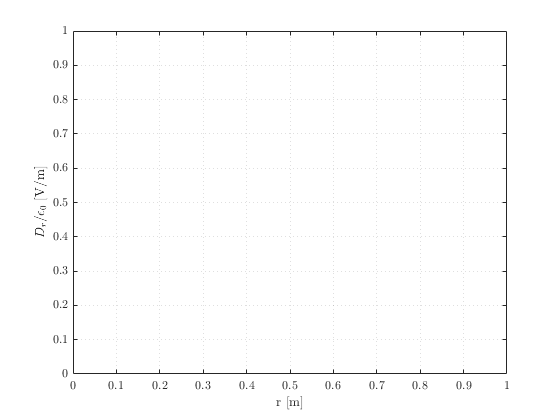


fDr = figure;
H = 5;
W = 8;
fDr.PaperUnits='centimeters';
fDr.InvertHardcopy='on';
fDr.PaperSize=[W H];
fDr.PaperPosition=[0 0 W H];

axDr = axes(fDr);
hold on
xlabel('r [m]')
ylabel('$D_r/\epsilon_0$ [V/m]')
grid on, box on

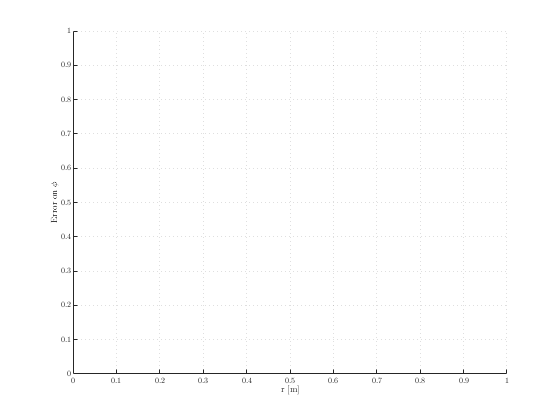


fD = figure;
H = 5;
W = 8;
fD.PaperUnits='centimeters';
fD.InvertHardcopy='on';
fD.PaperSize=[W H];
fD.PaperPosition=[0 0 W H];

axD = axes(fD);
axD.FontSize = 6;
hold on
xlabel('r [m]')
ylabel('Error on $\phi$')
grid on, box off

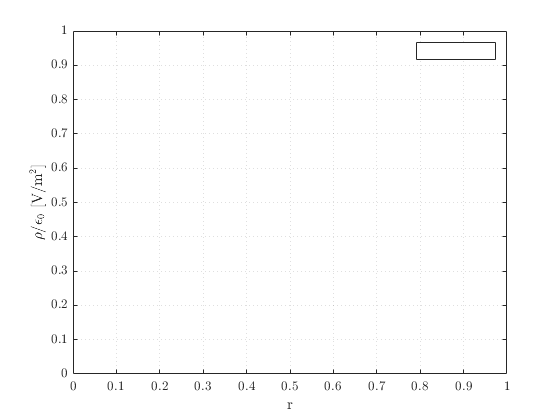


fRhoDif = figure;
H = 5;
W = 8;
fRhoDif.PaperUnits='centimeters';
fRhoDif.InvertHardcopy='on';
fRhoDif.PaperSize=[W H];
fRhoDif.PaperPosition=[0 0 W H];

axRhoDiff = axes(fRhoDif);
hold on
xlabel('r')
ylabel('$\rho/\epsilon_0$ [V/m$^2$]')
legend('show')
grid on, box on


fRho = figure;
H = 5;
W = 8;
fRho.PaperUnits='centimeters';
fRho.InvertHardcopy='on';
fRho.PaperSize=[W H];
fRho.PaperPosition=[0 0 W H];

axRho = axes(fRho);
hold on
xlabel('r')
ylabel('$\rho/\epsilon_0$ [V/m$^2$]')
legend('show')
grid on, box on


first = zeros(1,nsimul);


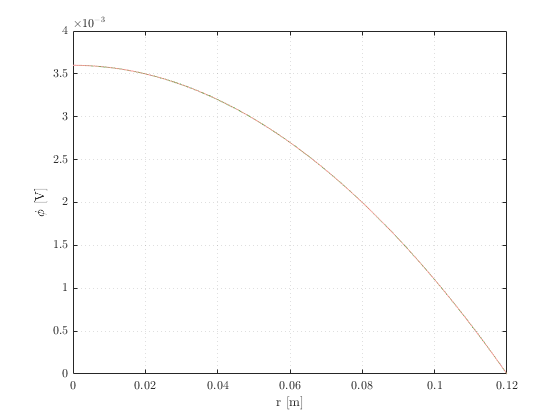

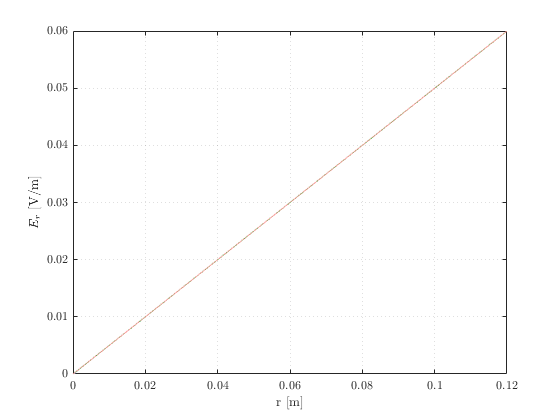

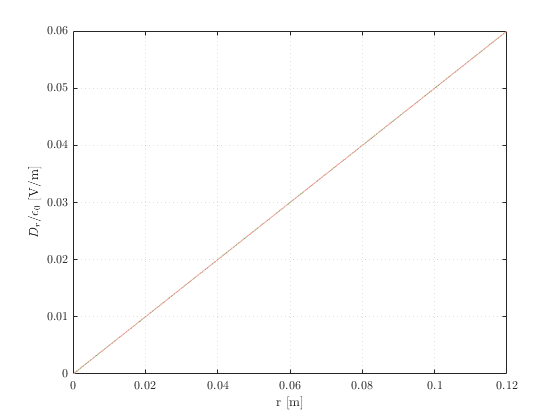

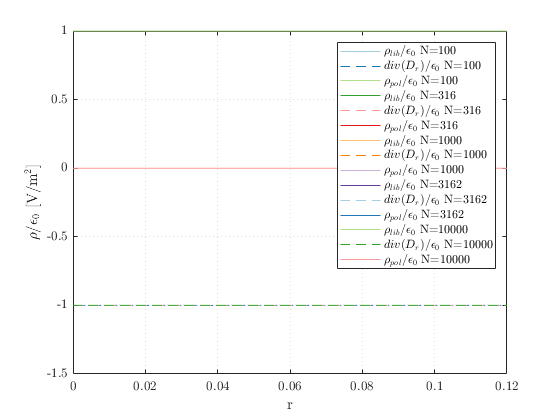

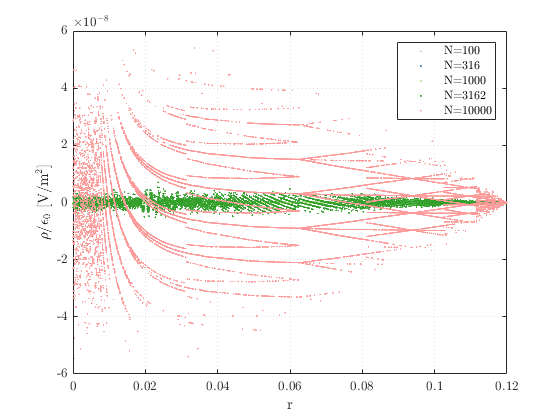



for i = 1:nsimul % Parcours des resultats de toutes les simulations
    
    filename = output{i};
    
    data = load([filename '_Er_Dr.out']);
    rmid = data(:,1);
    Er = data(:,2);
    Dr = data(:,3);
    data = load([filename '_phi.out']);
    r = data(:,1);
    phi = data(:,2);
    data = load([filename '_rholib_divEr_divDr.out']);
    rmidmid = data(:,1);
    rholib = data(:,2);
    divEr = data(:,3);
    divDr = data(:,4);
    
    plot(axPhi,r,phi)
    plot(axD,r,phi-(0.12^2-r.^2)/4,'.')
    
    plot(axEr,rmid,Er)
    
    plot(axDr,rmid,Dr)
    
    plot(axRho,rmidmid,rholib,'DisplayName',['$\rho_{lib}/\epsilon_0$ ' filename])
    plot(axRho,rmidmid,-divDr,'--','DisplayName',['$div(D_r)/\epsilon_0$ ' filename])
   plot(axRho,rmidmid,divEr-divDr,'DisplayName',['$\rho_{pol}/\epsilon_0$ ' filename])
   
   plot(axRhoDiff,rmidmid,rholib-divDr,'.','DisplayName',filename,'MarkerSize',4)
    
    
    first(i) = phi(1);
    
    
   
end

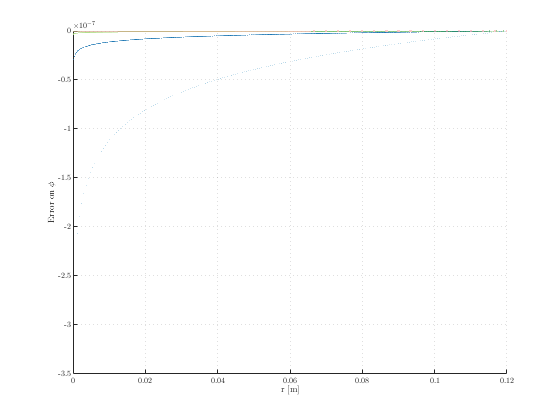

 print(fD,'fullConv1','-depsc2','-r300')



fConv = figure();

H = 5;
W = 8;
fConv.PaperUnits='centimeters';
fConv.InvertHardcopy='on';
fConv.PaperSize=[W H];
fConv.PaperPosition=[0 0 W H];
ax = axes(fConv,'Box','off');


error = abs((0.12)^2/4-first)

error = 	1.0e+-6 *

    0.3268    0.0379    0.0043    0.0005    0.0001





convfit = fit(log(N*2)',log(error)', 'poly1')

convfit =      Linear model Poly1:
     convfit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -1.897  (-1.916, -1.878)
       p2 =      -4.863  (-5.014, -4.712)


pfit = loglog(2*N,exp(convfit(log(N*2))),'Color',M('light green'), 'LineWidth',0.5);
hold on;
loglog(N*2,error,'+','MarkerEdgeColor',M('dark blue'), 'MarkerSize',4)
box off;
grid on;

ax.FontSize = 6;
ax.MinorGridLineStyle = 'none'

ax =   Axes with properties:

             XLim: [100 20000]
             YLim: [1.0000e-11 1.0000e-06]
           XScale: 'log'
           YScale: 'log'
    GridLineStyle: ':'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.GridLineStyle = '-'

ax =   Axes with properties:

             XLim: [100 20000]
             YLim: [1.0000e-11 1.0000e-06]
           XScale: 'log'
           YScale: 'log'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


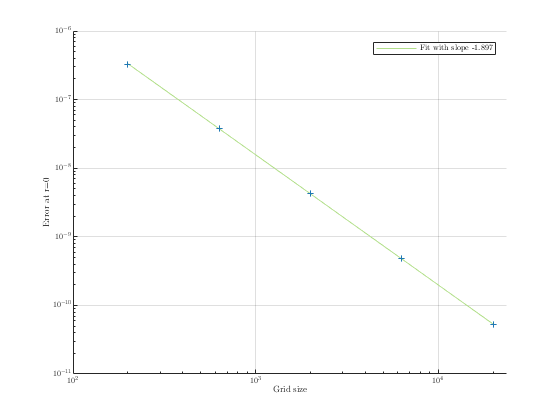

xlim([100 23857])

xlabel('Grid size')
ylabel('Error at r=0')

legend(pfit, ['Fit with slope ' num2str(convfit.p1)],'FontSize',6)

print(fConv,'Convergence','-depsc2','-r300')